sentFile = ["1_Room_noSEPA_sent.dat"
    "2_Room_noSEPA_sent_b.dat"
    "4_Room_txSEPA_sent_b.dat"
    "6_Room_rxSEPA_sent_b.dat"
    ];

sent_cnt = length(sentFile);

recvFile = ["1_Room_noSEPA_recv.dat"
    "2_Room_noSEPA_recv_b.dat"
    "4_Room_txSEPA_recv_b.dat"
    "6_Room_rxSEPA_recv_b.dat"
    ];
    
recv_cnt = length(recvFile);

nretx = [];
result = [];
delay = [];
diversity = [];
snr= [] ;
rssi = [];

recv_len = [];
for cnt = 1:1:sent_cnt
    
    sent_array= csvread(sentFile(cnt));
    recv_array = csvread(recvFile(cnt));
    
    
    nretx = [nretx mean(sent_array(:,1))];
    result = [result mean(sent_array(:,2))];
    delay = [delay mean(sent_array(:,3))];
    
    diversity = [diversity mean(recv_array(:,1))];
    snr = [snr mean(recv_array(:,2))];
    rssi = [rssi mean(recv_array(:,3))];
    
    recv_len = [recv_len length(recv_array')]
end

recv_len = 757

recv_len =    757   826


recv_len =    757   826   912


recv_len =    757   826   912   997


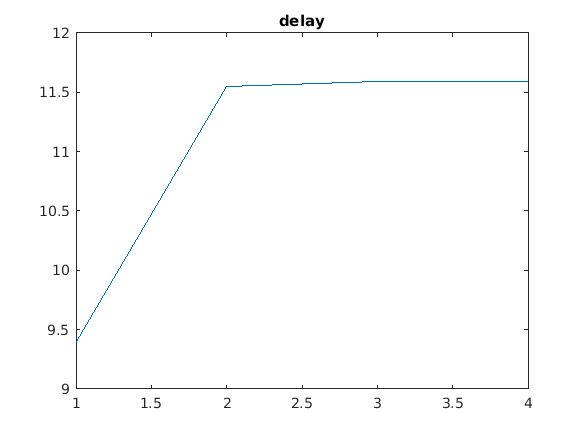



plot(delay);
title("delay");

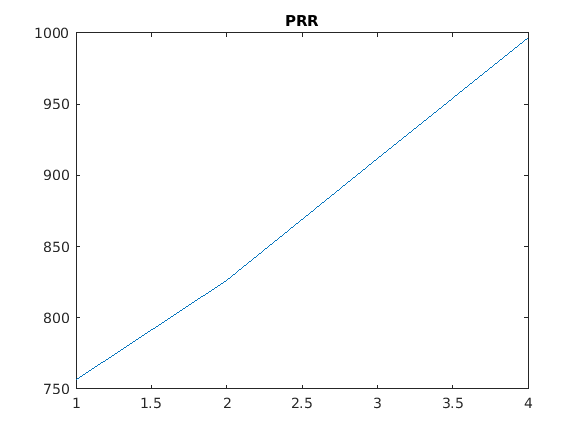

plot(recv_len);
title("PRR");

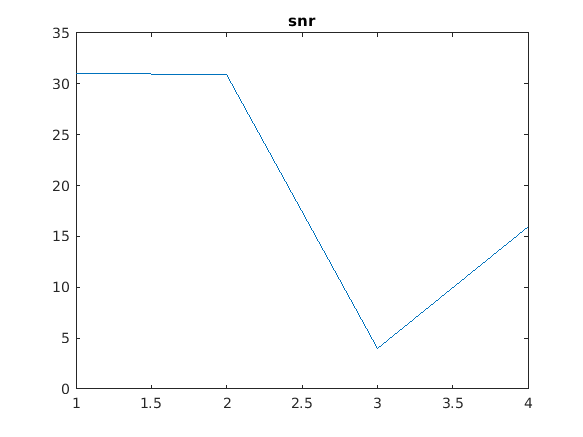

plot(snr);
title("snr");

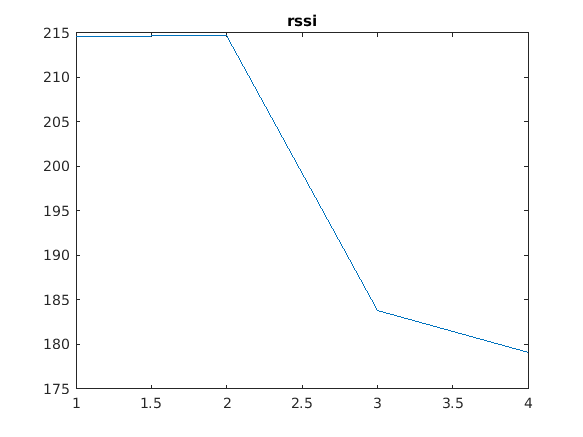

plot(rssi);
title("rssi");